clear
clc
close all

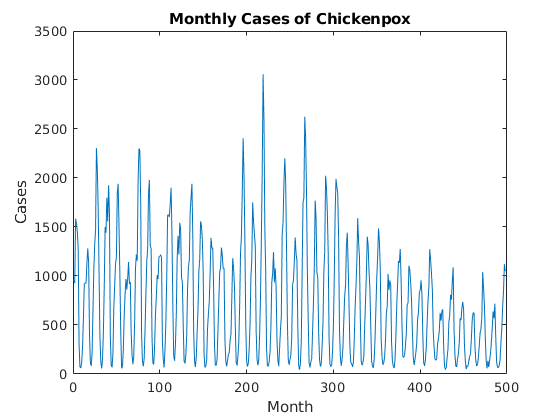

data = chickenpox_dataset;
data = [data{:}];

figure
plot(data)
xlabel("Month")
ylabel("Cases")
title("Monthly Cases of Chickenpox")

numTimeStepsTrain = floor(0.9*numel(data));

dataTrain = data(1:numTimeStepsTrain+1);
dataTest = data(numTimeStepsTrain+1:end);

mu = mean(dataTrain);
sig = std(dataTrain);

dataTrainStandardized = (dataTrain - mu) / sig;

XTrain = dataTrainStandardized(1:end-1);
YTrain = dataTrainStandardized(2:end);

numFeatures = 1;
numResponses = 1;
numHiddenUnits = 200;

layers = [ ...
    sequenceInputLayer(numFeatures)
    lstmLayer(numHiddenUnits)
    fullyConnectedLayer(numResponses)
    regressionLayer];

options = trainingOptions('adam', ...
    'MaxEpochs',250, ...
    'GradientThreshold',1, ...
    'InitialLearnRate',0.005, ...
    'LearnRateSchedule','piecewise', ...
    'LearnRateDropPeriod',125, ...
    'LearnRateDropFactor',0.2, ...
    'Verbose',0, ...
    'Plots','training-progress');

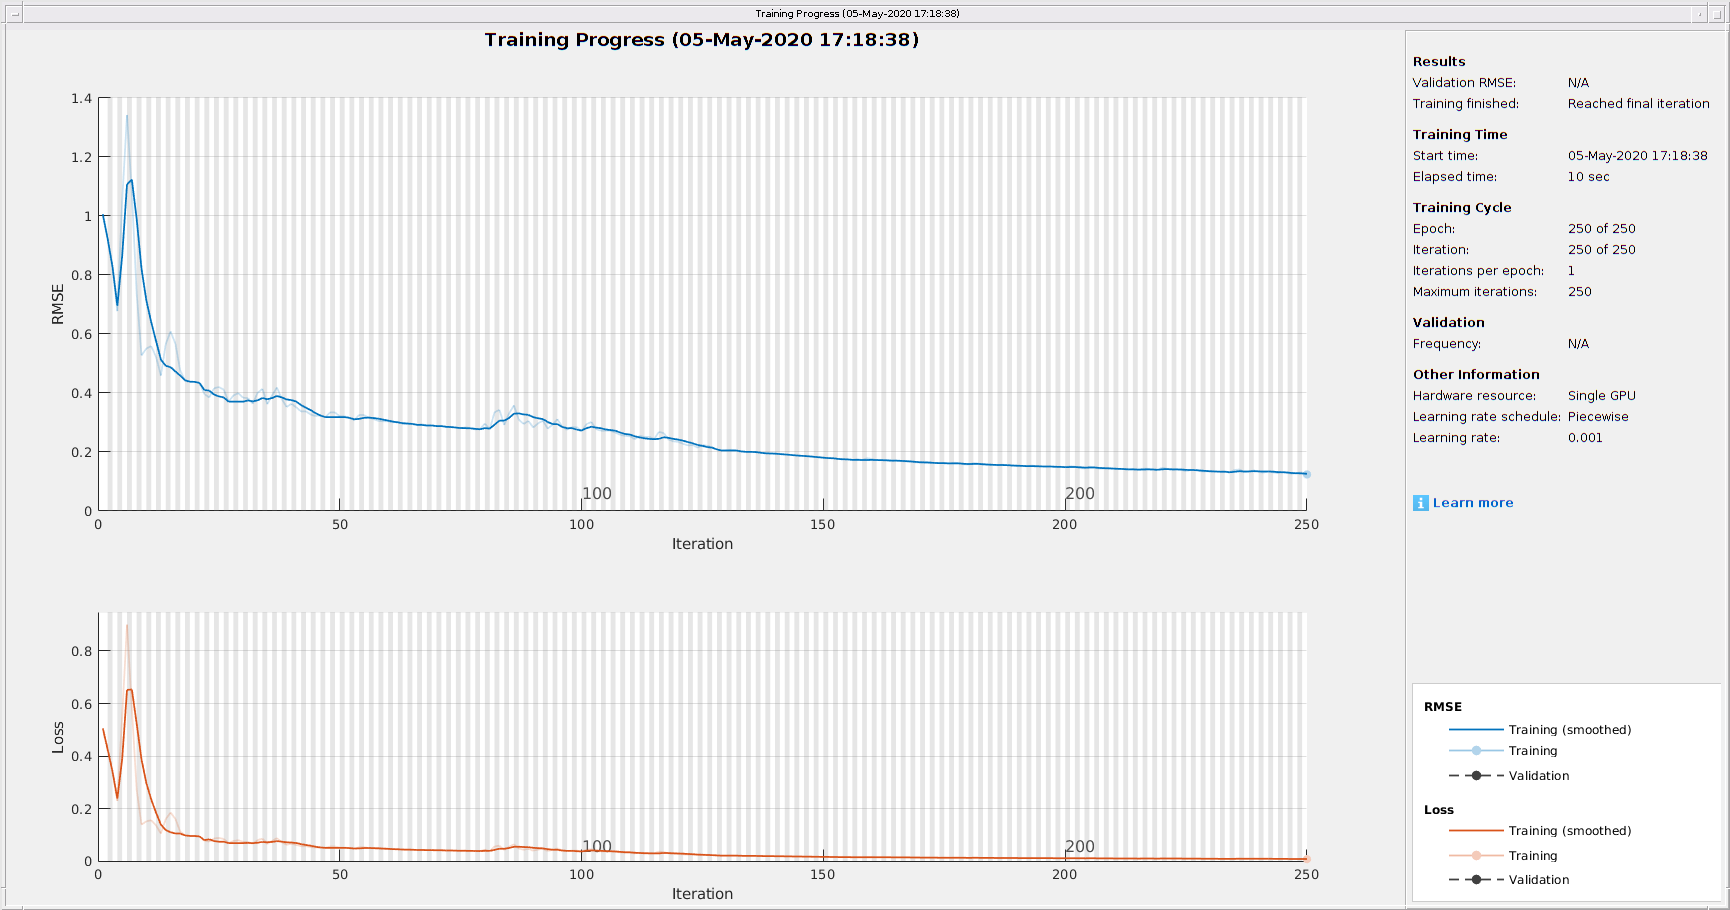

net = trainNetwork(XTrain,YTrain,layers,options);

dataTestStandardized = (dataTest - mu) / sig;
XTest = dataTestStandardized(1:end-1);

net = predictAndUpdateState(net,XTrain);
[net,YPred] = predictAndUpdateState(net,YTrain(end));

numTimeStepsTest = numel(XTest);
for i = 2:numTimeStepsTest
    [net,YPred(:,i)] = predictAndUpdateState(net,YPred(:,i-1),'ExecutionEnvironment','cpu');
end

YPred = sig*YPred + mu;

YTest = dataTest(2:end);
rmse = sqrt(mean((YPred-YTest).^2))

rmse = single
167.2852

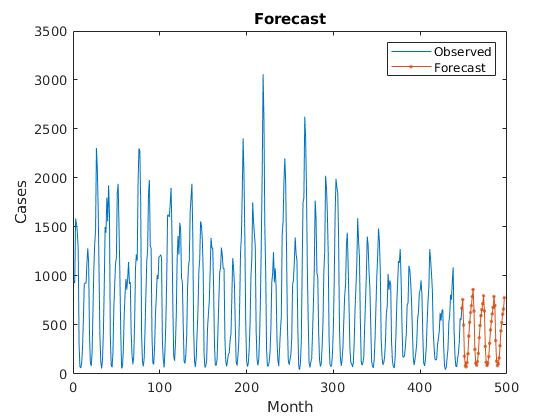

figure
plot(dataTrain(1:end-1))
hold on
idx = numTimeStepsTrain:(numTimeStepsTrain+numTimeStepsTest);
plot(idx,[data(numTimeStepsTrain) YPred],'.-')
hold off
xlabel("Month")
ylabel("Cases")
title("Forecast")
legend(["Observed" "Forecast"])